clc
clear

ke=1000;
kp=500;
elasticdt=0.005;
plasticdt=0.005/100;
%initial value
Qa=[0;0;0;0;0;0];
q=[0;0;0;0;0;0];
Qy=1000;
jj=1;
for i=0:elasticdt:20
    Q(1,jj)=1*i^2;
    Q(2,jj)=2*i^2;
    Q(3,jj)=3*i^2;
    Q(4,jj)=4*i^2;
    Q(5,jj)=5*i^2;
    Q(6,jj)=6*i^2;
    jj=jj+1;
end
dotQ(:,1)=zeros(6,1);
for i=2:size(Q,2)
    dotQ(:,i)=(Q(:,i)-Q(:,i-1))/elasticdt;
end

if norm(Q(:,1))-Qy>0
else
    iflag=0;
end

for i=1:4000
    if iflag==0
        q(:,i+1)=q(:,i)+(dotQ(:,i+1)/ke)*elasticdt;
        Qa(:,i+1)=Qa(:,i)+dotQ(:,i+1)*elasticdt;
        if norm(Q(:,i+1))-Qy>0
            if Q(:,i+1)'*dotQ(:,i+1)<0
                iflag=0;
                q(:,i+1)=q(:,i)+(dotQ(:,i+1)/ke)*elasticdt;
                Qa(:,i+1)=Qa(:,i)+dotQ(:,i+1)*elasticdt;
            else
                iflag=1;
                i
                syms dt
                f=Q(:,i)+dotQ(:,i+1)*dt;
                f1=norm(f)-Qy;
                dt1=solve(f1,dt);
                dt=double(dt1);
                aa=find (dt<0);
                dt(aa)=[];
                q(:,i+1)=q(:,i)+(dotQ(:,i+1)/ke)*dt;
                Q(:,i+1)=Q(:,i)+dotQ(:,i+1)*dt;%Qton
                Qa(:,i+1)=Qa(:,i)+dotQ(:,i+1)*dt;
                elat=(i)*elasticdt+dt;
                jj=i+2
                for ill=elat+plasticdt:plasticdt:20-elat
                    Q(1,jj)=1*ill^2;
                    Q(2,jj)=2*ill^2;
                    Q(3,jj)=3*ill^2;
                    Q(4,jj)=4*ill^2;
                    Q(5,jj)=5*ill^2;
                    Q(6,jj)=6*ill^2;
                    jj=jj+1;
                end
                for i1=i+2:size(Q,2)
                    dotQ(:,i1)=(Q(:,i1)-Q(:,i1-1))/plasticdt;
                end
                ik=1;
            end
        end
    end
    if iflag==1 && ik==0
        q(:,i+1)=q(:,i)+(Qa(:,i)'*dotQ(:,i+1)*Qa(:,i)/(kp*Qy*Qy)+dotQ(:,i+1)/ke)*plasticdt;
        Qa(:,i+1)=Qa(:,i)+(-Qa(:,i)'*dotQ(:,i+1)*Qa(:,i)/(Qy*Qy)+dotQ(:,i+1))*plasticdt;
        if Q(:,i+1)'*dotQ(:,i+1)<0
            iflag=0;
            q(:,i+1)=q(:,i)+(dotQ(:,i+1)/ke)*elasticdt;
            Qa(:,i+1)=Qa(:,i)+dotQ(:,i+1)*elasticdt;
        end
    end
    ik=0;
end

i = 2048

jj = 2050

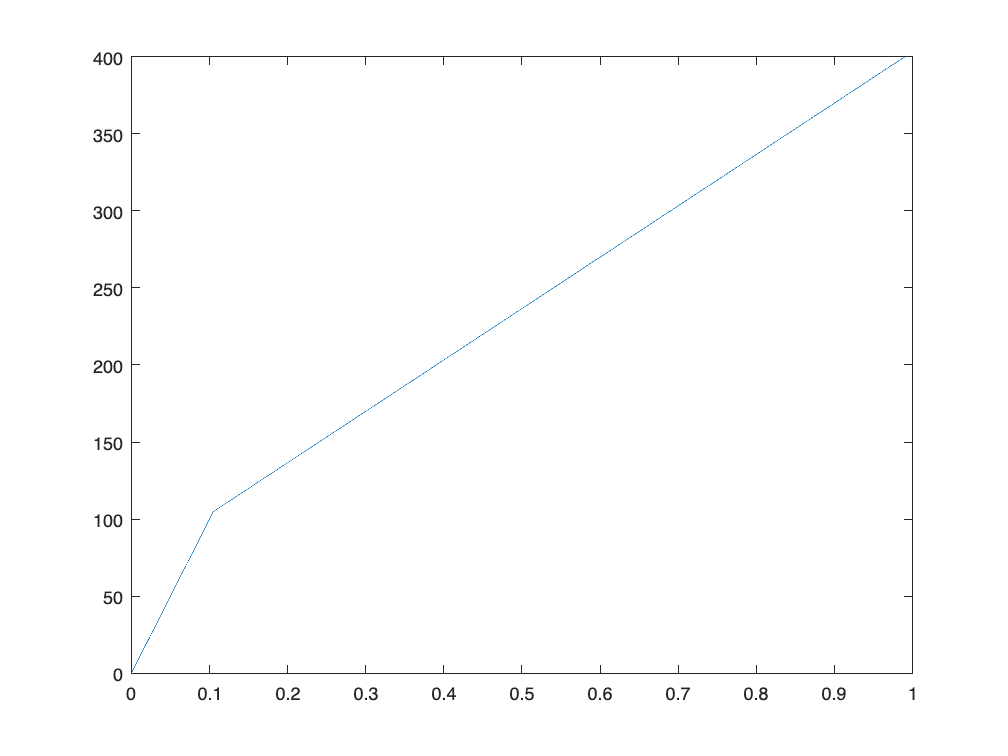

plot(q(1,1:4001),Q(1,1:4001))